# Geoscience Data Analysis

*D. Hasterok (derrick.hasterok@adelaide.edu.au)*

*Dept. of Earth Sciences, University of Adelaide, North Terrace, Adelaide, SA 5005*

# 7 Missing and Censored Data

addpath ../codes
addpath ../data

clear all;

## 7.1 Introduction

"Reports that say that something hasn't happened are always interesting to me, because as we know, there are known knowns; there are things we know we know. We also know there are known unknowns; that is to say we know there are some things we do not know. But there are also unknown unknowns—the ones we don't know we don't know. And if one looks throughout the history of our country and other free countries, it is the latter category that tend to be the difficult ones."  Donald Rumsfeld, the former Secretary of Defense under George W. Bush, once spoke these works and left more than one person scratching their head.  While I'm no fan of Rumsfeld's policies, I think he was absolutely correct on this point and it is a reasonable description of our relationship to data.  Let me elaborate. When we collect data, we get values for those data.

- We know what the values are: they are a *known knowns*.  Ordinary data.

- Sometimes we collect data and we don't know exactly what the values are, but we have some constraints: a *known unknowns*.  These data can be ones for which the values are outside the bounds of our measuring device or rounded data.

- There are data we don't collect: *unknown unknowns*.  Or samples that didn't work out or were dropped from a series (time or space) or—let's hope not—are lost or deleted.  Basically, we have no constraints on these values.

- And to add to Rumsfeld's list, there are data we know, we just don't realize it yet: *unknown knowns*.  These data are unknown, but we know something about them and can modeled or estimated the values by proxy.

Hopefully you will know the values of all your data because it will make analysis easier.  Missing data are not a problem for data analyses since we do not know what their values should be.  Missing data are as if we didn't collect the data in the first place.  If we want to estimate the values of missing data, then interpolation and extrapolation or model prediction are required.  The ultimate goal of all our work is to predict the unknown based on our knowns—*science!*

The real problem, and one you are likely to come across at some point, are data that are off-scale, too large or too small to measure properly.  To statisticians, data which are outside the measurable bounds are called ***censored***.  There are three types of censored data: ***left-censored***, data that fall below a detection limit; ***right-censored***, data that are greater than our maximum detectable value; and ***interval censored***, data that are rounded (generally to too few digits). Properly treating censored data in all cases is beyond the scope of this course, but there is a good text by Helsel, which discusses how to handle these data properly in a variety of contexts.  In my experience, values below detection are more common than those that are above detection so we will focus on how to incorporate left-centered data into an analysis.

## 7.2 Good and Bad Practice

Censored data can be a pain to deal with because it isn't always clear what to do and the methods have not been developed to handle every test or analytical procedure you wish to perform.  Censored data have values, though we have limited knowledge of the values.  There is a temptation to do one of four things with left-censored data and all should be avoided.

- Never replace censored data with a zero, doing so will bias the data to low values;

- Never replace censored data with the detection limit, doing so will bias the data to high values; 

- Never drop censored data, doing so will bias data to high values even worse than replacing with the detection limit; and

- Never replace with a value, if you don't know what it should be you are simply making up data, which can have adverse effects on hypothesis tests, fitting, and estimation of scale parameters.

However, there are a few things you can do when data are censored data.  Recall that a median simply represents the value associated with 50% of the data.  So if less than half of the data are censored, you can still determine the so long as the censored data are sufficiently above or below the median.

For geochemical data in particular, selected trace elements concentrations are often correlated, so even if one element is below detection, the other may not be.  The relationship between two correlated elements makes it possible to predict the value of the element below detection including an uncertainty.  If there are several elements that correlate, generally the case, then a more robust estimate can be made.  While this is replacing the value, it is doing so with a model that has some predictive power and is therefore a valid method.  Predicting the concentration of a below detection value in this manner is actually preferable to using the censoring techniques discussed below because they are less constrained.

## 7.3 Distributions

### 7.3.1 Cumulative Density Function

There are a few methods to estimate the CDF with censored data, I use the method by Michael and Schucany (1986).  The first step in with any censored data is to sort the sample set by value with left-censored data placed just below the value of detection (e.g., 8, 5, 1, <5, 13, <5 sorted will be 1, <5, <5, 5, 8, 13).  Once the data are sorted, we can assign an index value to each value.  For the index positions associated with non-censored data, $\Omega$ of length $M$, we estimate the quantile probabilities, $C_i$, for the $j$-th non-censored position in the $i$-th position of the ordered sample set,


$$C_i(a) = \frac{N - a + 1}{N - 2a + 1} \prod_{j \in \Omega, j \geq i} \frac{j - a}{j - a + 1}$$


where $a \in (0,1)$, a value of $a = 3/8$ is recommended.  Note the product has been reversed in terms of indices.  In our example above, $\Omega = \{1,4,5,6\}$.  The table below clarifies the indicies with the associated values.


$$\begin{array}{ccccccc} i & 1 & 2 & 3 & 4 & 5 & 6 \\ j & 1 & & & 4 & 5 & 6 \\ k & 1 & & & 2 & 3 & 4 \\ x_{(i)} & 1 & <5 & <5 & 5 & 8 & 13 \\ C_i(3/8) & 0.22 &  & & 0.58 & 0.74 & 0.90 \end{array}$$


The values of $x_{(i)}$ are plotted versus $p_i$ to produce the empirical CDF.  Note the increase in probability between $x_{(i)}$ of 1 and 5 is greater than between 5 and 8 and 8 and 13, accounting for the non-detection values.  Changing $a$ will have an effect on the quantile probabilities, but as the number of samples grow, it is less important.

To estimate the mean, $\bar{x}$, and variance, $s^2$, we use Kaplan-Meier-based estimators,


$$\bar{x} = \sum_{j \in \Omega} x_{(j)} (C_{j+1} - C_j)$$



$$s^2 = \frac{N}{N - 1} \sum_{j \in \Omega} (x_{(j)} - \bar{x})^2(C_{j+1} - C_j)$$


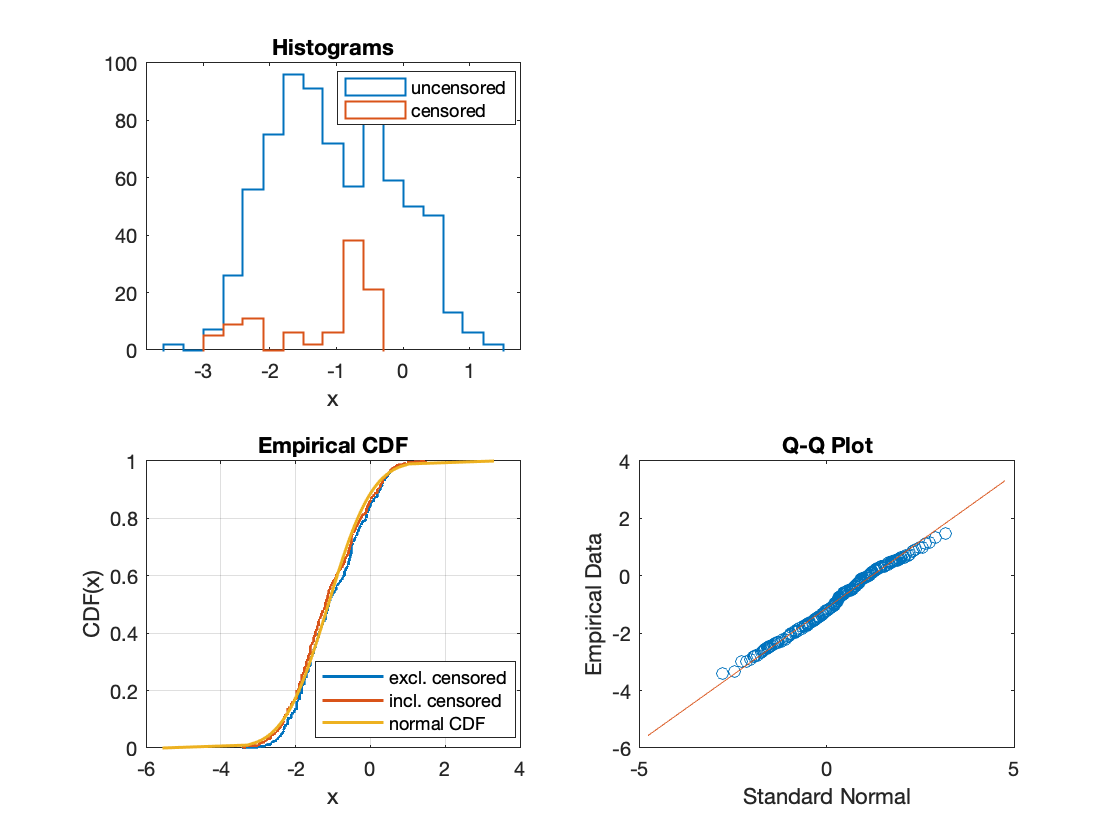

model = struct with fields:
          mu: -1.1270
       sigma: 0.9327
    sigma_mu: 3.8592e-04
         rms: 0.0136


data = readtable('cascades.xlsx');

model = gausscensor(data.sb_ppm,'plot','scale','log')

### 7.3.2 Probability Density Function

A PDF is simply the derivative of the CDF. Hence, once we have the CDF, computing the PDF is simple.  From the cumulative probabilities above, the PDF is given by


$$P_i(x_{(i)}) = (C_{i+1} - C_i)$$


and when $x < x_{(1)}$ or $x > x_{(N)}$ $P = 0$.  This formulation allows us to plot a histogram of the measured probabilities.

## 7.4 Hypothesis Testing

Makes it more complicated.

## 7.5 Regression

In the process of learning how to do this myself.

**References**

Helsel, D. R. (2004), *Nondetects and Data Analysis: Statistics for Censored Environmental Data*, J. Wiley & Sons*, ***2004**